clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


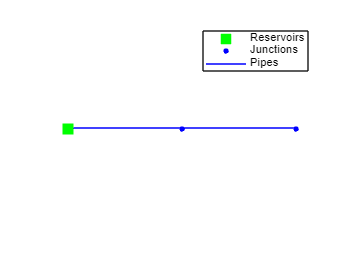

ans =   Axes with properties:

             XLim: [-120 120]
             YLim: [-0.1000 0.1000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



% Initialize epanet class, without inputs.
setenv('MW_MINGW64_LOC', 'C:\mingw64')
d = epanet;

% Use gpm for flow units and the Hazen-Williams formula for head loss
d.apiENinit(d.ToolkitConstants.EN_GPM, d.ToolkitConstants.EN_HW, d.LibEPANET, d.ph);

% Add the primary Reservoir at an elevation of 800 ft
[index, ~]  = d.apiENaddnode('R1', d.ToolkitConstants.EN_RESERVOIR, d.LibEPANET, d.ph);
d.apiENsetnodevalue(index, d.ToolkitConstants.EN_ELEVATION, 800, d.LibEPANET, d.ph);
d.apiENsetcoord(index, -100, 0, d.LibEPANET, d.ph);

% Add Junction 1 (J1) at an elevation of 700 ft and a demand of 0 gpm
[index, ~]  = d.apiENaddnode('J1', d.ToolkitConstants.EN_JUNCTION, d.LibEPANET, d.ph);
d.apiENsetjuncdata(index, 700, 0, '', d.LibEPANET, d.ph);
d.apiENsetcoord(index, 0, 0, d.LibEPANET, d.ph);

% Add Junction 2 (J2) at an elevation of 650 ft and a demand of 50 gpm
[index, ~]  = d.apiENaddnode('J2', d.ToolkitConstants.EN_JUNCTION, d.LibEPANET, d.ph);
d.apiENsetjuncdata(index, 650, 50, '', d.LibEPANET, d.ph);
d.apiENsetcoord(index, 100, 0, d.LibEPANET, d.ph);

% Add Pipe 1 connecting Reservoir (R1) to Junction 1 (J1)
% Length = 1000 ft, Diameter = 12 in, Roughness = 100, Minor Loss = 0
[index, ~] = d.apiENaddlink('P1', d.ToolkitConstants.EN_PIPE, 'R1', 'J1', d.LibEPANET, d.ph);
d.apiENsetpipedata(index, 1000, 12, 100, 0, d.LibEPANET, d.ph);

% Add Pipe 2 connecting Junction 1 (J1) to Junction 2 (J2)
% Length = 1500 ft, Diameter = 8 in, Roughness = 100, Minor Loss = 0
[index, ~] = d.apiENaddlink('P2', d.ToolkitConstants.EN_PIPE, 'J1', 'J2', d.LibEPANET, d.ph);
d.apiENsetpipedata(index, 1500, 8, 100, 0, d.LibEPANET, d.ph);

% Save the custom gravity network project for future use
d.apiENsaveinpfile('MyCustomNetwork.inp', d.LibEPANET, d.ph);

% Plot network & close 
d.plot

d.apiENclose(d.LibEPANET, d.ph);
d.unload;